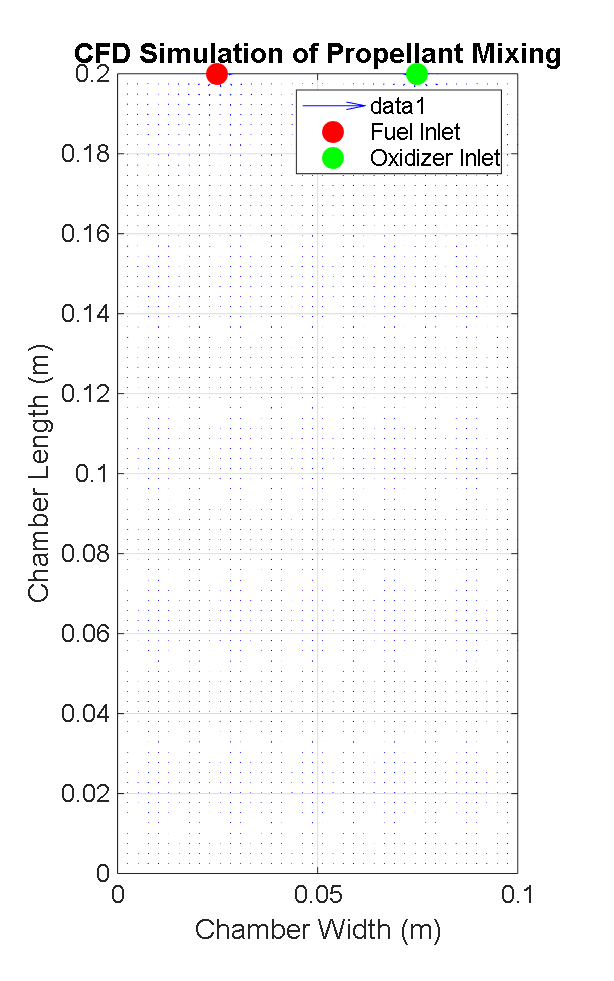

% --- MATLAB CFD Simulation: Cryogenic Injector Flow ---
% This script models the fluid kinematics of fuel and oxidizer streams
% entering the combustion chamber.

clear; clc; close all;

%% 1. Define the Geometry and Grid (The "Swimming Pool")
% We define a 2D chamber, 10cm wide and 20cm tall.
x = linspace(0, 0.1, 40); % 40 points in x-direction
y = linspace(0, 0.2, 80); % 80 points in y-direction
[X, Y] = meshgrid(x, y);  % Create the 2D grid of "sensors"

%% 2. Define the Boundary Conditions (The "Jets" and "Walls")
% We will model two inlet streams at the top of the chamber.
% We use the concept of a "source" to model each inlet.

% --- Fuel Inlet ---
x_fuel = 0.025; % x-position of the fuel inlet (2.5 cm)
y_fuel = 0.2;   % y-position (top of the chamber)
strength_fuel = 1; % Strength of the fuel jet

% --- Oxidizer Inlet ---
x_ox = 0.075;   % x-position of the oxidizer inlet (7.5 cm)
y_ox = 0.2;     % y-position (top of the chamber)
strength_ox = 1;  % Strength of the oxidizer jet

%% 3. Calculate the Flow Field (Solve the Physics)
% These equations calculate the velocity components (u, v) at every
% grid point based on the influence of the two inlet "sources".

% Distance from each grid point to the fuel source
r_fuel = sqrt((X - x_fuel).^2 + (Y - y_fuel).^2);
% Distance from each grid point to the oxidizer source
r_ox = sqrt((X - x_ox).^2 + (Y - y_ox).^2);

% Calculate the x and y velocity components
u = (strength_fuel * (X - x_fuel) ./ r_fuel.^2) + (strength_ox * (X - x_ox) ./ r_ox.^2);
v = (strength_fuel * (Y - y_fuel) ./ r_fuel.^2) + (strength_ox * (Y - y_ox) ./ r_ox.^2);

%% 4. Visualize the Result
figure('Name', 'MATLAB CFD of Injector Flow', 'Position', [100, 100, 500, 800]);

% Use 'quiver' to draw an arrow at each grid point showing the velocity
quiver(X, Y, u, v, 'b');

% Add formatting for a professional plot
hold on;
% Mark the inlets
plot(x_fuel, y_fuel, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Fuel Inlet');
plot(x_ox, y_ox, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Oxidizer Inlet');
hold off;

title('CFD Simulation of Propellant Mixing');
xlabel('Chamber Width (m)');
ylabel('Chamber Length (m)');
axis equal; axis([0 0.1 0 0.2]);
legend('show');
grid on;
set(gca, 'FontSize', 12);

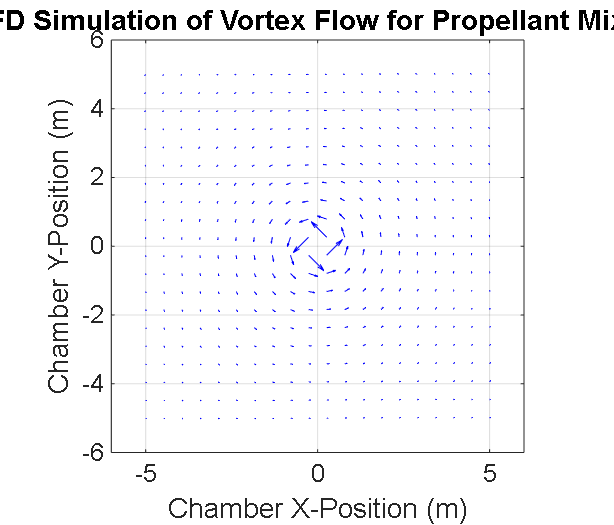

% --- MATLAB CFD Simulation: Vortex Flow in a Chamber ---
% This script models the swirling vortex motion used to enhance
% propellant mixing inside a combustion chamber.

clear; clc; close all;

%% 1. Define the Geometry and Grid
% We define a square chamber for this visualization.
x = linspace(-5, 5, 20); % 20 points from -5 to 5
y = linspace(-5, 5, 20); % 20 points from -5 to 5
[X, Y] = meshgrid(x, y);  % Create the 2D grid

%% 2. Define the Vortex Properties
% We will model a single, central vortex.
vortex_strength = 20; % This controls the speed of the swirl

%% 3. Calculate the Flow Field (Solve the Physics)
% These are the standard equations for the velocity field of a 2D vortex.
% Note: r_sq is the squared distance from the center to each point.
r_sq = X.^2 + Y.^2;

% The velocity components are perpendicular to the radial direction.
% We add a small number (eps) to r_sq to avoid division by zero at the center.
u = -vortex_strength * Y ./ (r_sq + eps); % x-component of velocity
v =  vortex_strength * X ./ (r_sq + eps); % y-component of velocity

%% 4. Visualize the Result
figure('Name', 'MATLAB CFD of Vortex Flow', 'Position', [100, 100, 700, 600]);

% Use 'quiver' to draw an arrow at each grid point showing the velocity
quiver(X, Y, u, v, 'b');

% Add formatting for a professional plot
title('CFD Simulation of Vortex Flow for Propellant Mixing');
xlabel('Chamber X-Position (m)');
ylabel('Chamber Y-Position (m)');
axis equal; axis([-6 6 -6 6]);
grid on;
set(gca, 'FontSize', 12);

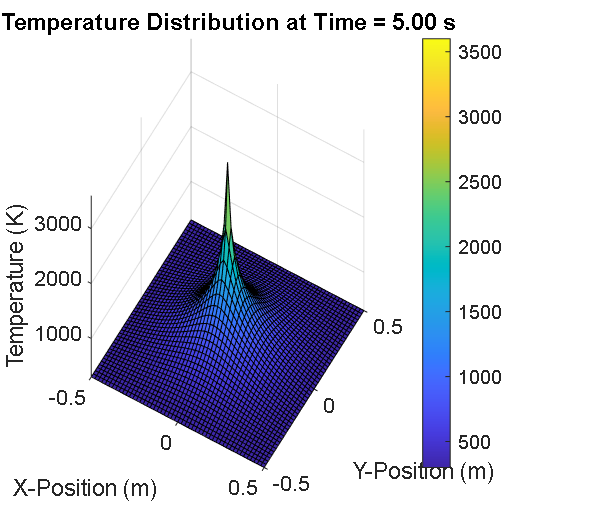

% --- MATLAB CFD Simulation: Heat Diffusion from Combustion ---
% This script models how heat from a central ignition point spreads
% throughout the combustion chamber over time.

clear; clc; close all;

%% 1. Define the Geometry and Grid
% We define a 2D chamber grid.
grid_size = 51; % Number of points in each direction (must be odd)
L = 1;          % Length of the chamber side (m)
dx = L / (grid_size - 1); % Spatial step size
x = linspace(-L/2, L/2, grid_size);
y = linspace(-L/2, L/2, grid_size);
[X, Y] = meshgrid(x, y);

%% 2. Define Physical Properties and Initial Conditions
alpha = 0.01; % Thermal diffusivity of the gas (m^2/s)
T_cool = 300; % Initial temperature of the chamber (K)
T_hot = 3600; % Temperature of the central ignition point (K)

% Initialize the temperature grid
T = ones(grid_size, grid_size) * T_cool;

% Set the central point to the hot ignition temperature
center_idx = ceil(grid_size / 2);
T(center_idx, center_idx) = T_hot;

%% 3. Set Up the Simulation
dt = 0.1 * dx^2 / alpha; % Time step (for stability)
t_final = 5;             % Total simulation time
n_steps = floor(t_final / dt);

%% 4. Visualize the Initial State
figure('Name', 'Heat Diffusion in Combustion Chamber', 'Position', [100, 100, 700, 600]);
h_surf = surf(X, Y, T);
title(sprintf('Temperature Distribution at Time = 0.00 s'));
xlabel('X-Position (m)');
ylabel('Y-Position (m)');
zlabel('Temperature (K)');
zlim([T_cool T_hot]);
colorbar;
view(30, 45); % Set 3D view angle

%% 5. Run the Simulation (Solve the Physics)
% This loop iteratively calculates the temperature at the next time step
% based on the current temperatures of its neighbors.
for n = 1:n_steps
    T_old = T;
    for i = 2:grid_size-1
        for j = 2:grid_size-1
            % The 2D finite difference equation for heat diffusion
            T(i,j) = T_old(i,j) + (alpha * dt / dx^2) * ...
                   (T_old(i+1,j) + T_old(i-1,j) + T_old(i,j+1) + T_old(i,j-1) - 4*T_old(i,j));
        end
    end
    
    % Keep the center point as a constant hot source
    T(center_idx, center_idx) = T_hot;
    
    % Update the plot every 50 steps for a smooth animation
    if mod(n, 50) == 0
        set(h_surf, 'ZData', T);
        title(sprintf('Temperature Distribution at Time = %.2f s', n * dt));
        drawnow;
    end
end

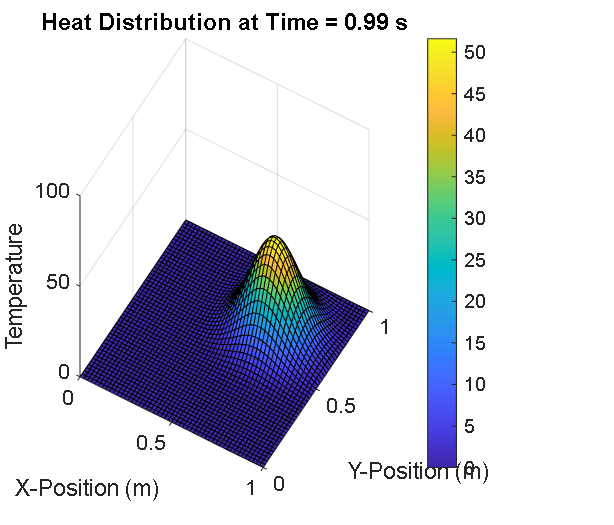

% --- MATLAB CFD Simulation: Convection-Diffusion of Heat ---
% This script models how a patch of hot gas is carried downstream by the
% fluid flow while also diffusing outwards.

clear; clc; close all;

%% 1. Define the Geometry and Grid
grid_size = 51;
L = 1; % Length of the chamber side (m)
dx = L / (grid_size - 1);
x = linspace(0, L, grid_size);
y = linspace(0, L, grid_size);
[X, Y] = meshgrid(x, y);

%% 2. Define Physical Properties and Initial Conditions
alpha = 0.001; % Thermal diffusivity (m^2/s)
u_flow = 0.5;  % Convective velocity in x-direction (m/s)
v_flow = 0.5;  % Convective velocity in y-direction (m/s)

% Initialize the temperature grid
T = zeros(grid_size, grid_size);

% Create an initial "hot spot" near the top-left corner
T(5:15, 5:15) = 100; % A square patch of hot gas (100 degrees)

%% 3. Set Up the Simulation
dt = 0.2 * dx / sqrt(u_flow^2 + v_flow^2); % Time step (for stability)
t_final = 1.0;
n_steps = floor(t_final / dt);

%% 4. Visualize the Initial State
figure('Name', 'Convection-Diffusion Simulation', 'Position', [100, 100, 700, 600]);
h_surf = surf(X, Y, T'); % Note the transpose (') for correct orientation
title(sprintf('Heat Distribution at Time = 0.00 s'));
xlabel('X-Position (m)');
ylabel('Y-Position (m)');
zlabel('Temperature');
zlim([0 100]);
colorbar;
view(30, 45);

%% 5. Run the Simulation (Solve the Physics)
% This loop iteratively calculates the temperature at the next time step
for n = 1:n_steps
    T_old = T;
    for i = 2:grid_size-1
        for j = 2:grid_size-1
            % Convection terms (how the flow carries heat)
            convection_x = u_flow * (T_old(i,j) - T_old(i-1,j)) / dx;
            convection_y = v_flow * (T_old(i,j) - T_old(i,j-1)) / dx;
            
            % Diffusion terms (how heat spreads out)
            diffusion = alpha * (T_old(i+1,j) + T_old(i-1,j) + T_old(i,j+1) + T_old(i,j-1) - 4*T_old(i,j)) / dx^2;
            
            % Combine to solve the Convection-Diffusion equation
            T(i,j) = T_old(i,j) - dt * (convection_x + convection_y) + dt * diffusion;
        end
    end
    
    % Update the plot every few steps for a smooth animation
    if mod(n, 5) == 0
        set(h_surf, 'ZData', T');
        title(sprintf('Heat Distribution at Time = %.2f s', n * dt));
        drawnow;
    end
end

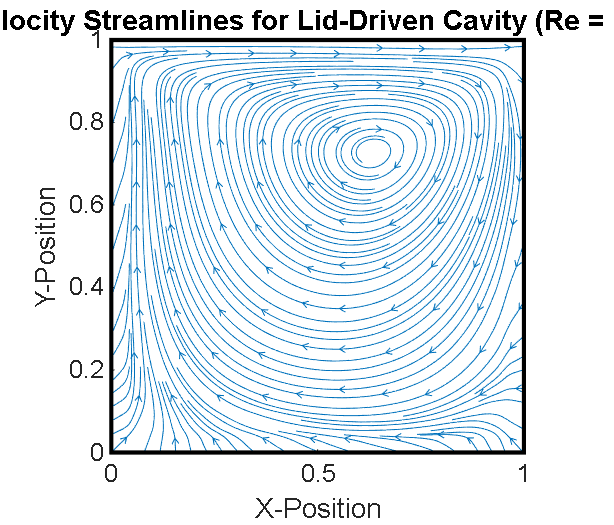

% --- MATLAB CFD: Lid-Driven Cavity (Navier-Stokes Solver) ---
% This script solves the 2D incompressible Navier-Stokes equations to
% simulate the flow inside a cavity with a moving top lid.

clear; clc; close all;

%% 1. Define Simulation Parameters
grid_points = 41; % Number of grid points in each direction
domain_size = 1.0; % Length of the square domain sides
dx = domain_size / (grid_points - 1); % Spatial step size
dy = dx;
Re = 100; % Reynolds number (characterizes the flow)
nu = 1 / Re; % Kinematic viscosity
dt = 0.001; % Time step
n_steps = 5000; % Number of simulation steps

% Initialize velocity and pressure fields
u = zeros(grid_points, grid_points); % x-velocity
v = zeros(grid_points, grid_points); % y-velocity
p = zeros(grid_points, grid_points); % pressure

%% 2. Main Simulation Loop (Solve the Physics)
for n = 1:n_steps
    % Store old values
    u_old = u;
    v_old = v;

    % --- Solve the Momentum Equations (Rules 1 & 2) ---
    for i = 2:grid_points-1
        for j = 2:grid_points-1
            % x-momentum equation
            u(i,j) = u_old(i,j) - dt * ( u_old(i,j)*(u_old(i,j) - u_old(i-1,j))/dx + v_old(i,j)*(u_old(i,j) - u_old(i,j-1))/dy ) ...
                   - dt/dx * (p(i+1,j) - p(i-1,j))/2 ...
                   + nu * dt * ( (u_old(i+1,j) - 2*u_old(i,j) + u_old(i-1,j))/dx^2 + (u_old(i,j+1) - 2*u_old(i,j) + u_old(i,j-1))/dy^2 );
            
            % y-momentum equation
            v(i,j) = v_old(i,j) - dt * ( u_old(i,j)*(v_old(i,j) - v_old(i-1,j))/dx + v_old(i,j)*(v_old(i,j) - v_old(i,j-1))/dy ) ...
                   - dt/dy * (p(i,j+1) - p(i,j-1))/2 ...
                   + nu * dt * ( (v_old(i+1,j) - 2*v_old(i,j) + v_old(i-1,j))/dx^2 + (v_old(i,j+1) - 2*v_old(i,j) + v_old(i,j-1))/dy^2 );
        end
    end

    % --- Solve the Pressure-Correction (Poisson) Equation ---
    % This step ensures mass is conserved
    for iter = 1:50 % Iterate to converge pressure
        p_old = p;
        for i = 2:grid_points-1
            for j = 2:grid_points-1
                p(i,j) = ( (p_old(i+1,j) + p_old(i-1,j))*dy^2 + (p_old(i,j+1) + p_old(i,j-1))*dx^2 ) / (2*(dx^2+dy^2)) ...
                       - (dx^2*dy^2)/(2*(dx^2+dy^2)) * ( (u(i+1,j)-u(i-1,j))/(2*dx) + (v(i,j+1)-v(i,j-1))/(2*dy) ) / dt;
            end
        end
    end
    
    % --- Apply Boundary Conditions ---
    u(1,:) = 0; u(end,:) = 0; u(:,1) = 0; % No-slip on left, right, bottom walls
    v(1,:) = 0; v(end,:) = 0; v(:,1) = 0; v(:,end) = 0;
    u(:,end) = 1.0; % Moving lid at the top wall (u=1, v=0)
end

%% 3. Visualize the Final Result
figure('Name', 'Lid-Driven Cavity Flow', 'Position', [100, 100, 700, 600]);
[x, y] = meshgrid(linspace(0,domain_size,grid_points));

% Use 'streamslice' to draw smooth streamlines of the flow
streamslice(x, y, u', v', 2);
hold on;
% Draw the box
rectangle('Position', [0 0 domain_size domain_size], 'LineWidth', 2);
hold off;

title(sprintf('Velocity Streamlines for Lid-Driven Cavity (Re = %d)', Re));
xlabel('X-Position');
ylabel('Y-Position');
axis equal; axis([0 domain_size 0 domain_size]);
set(gca, 'FontSize', 12);